# Test de Chi2

## Lire les données

opts=detectImportOptions('TD-foret-chi2_ent.xlsx')

opts =   SpreadsheetImportOptions with properties:

   Sheet Properties:
                        Sheet: ''

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'Var1', 'Var2', 'Var3' ... and 10 more}
                VariableTypes: {'char', 'char', 'char' ... and 10 more}
        SelectedVariableNames: {'Var1', 'Var2', 'Var3' ... and 10 more}
              VariableOptions: Show all 13 VariableOptions 
	Access Variabl

opts.VariableNamesRange="A1"

opts =   SpreadsheetImportOptions with properties:

   Sheet Properties:
                        Sheet: ''

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'Var1', 'Var2', 'Var3' ... and 10 more}
                VariableTypes: {'char', 'char', 'char' ... and 10 more}
        SelectedVariableNames: {'Var1', 'Var2', 'Var3' ... and 10 more}
              VariableOptions: Show all 13 VariableOptions 
	Access Variabl

opts.PreserveVariableNames=true

opts =   SpreadsheetImportOptions with properties:

   Sheet Properties:
                        Sheet: ''

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'Var1', 'Var2', 'Var3' ... and 10 more}
                VariableTypes: {'char', 'char', 'char' ... and 10 more}
        SelectedVariableNames: {'Var1', 'Var2', 'Var3' ... and 10 more}
              VariableOptions: Show all 13 VariableOptions 
	Access Variabl

foret = readtable('TD-foret-chi2_ent.xlsx',opts) % lire les données du tableau

foret = 569×13 table
         Nom du site           Région climatique     Type de feuillage    Caractère saisonnier            Espèce dominante            Latitude    Direction Latitude    Longitude    Direction Longitude    Altitude (m)    Biomasse aérienne totale (gC/cm²)      Var12                                            Var13                                     
    ______________________    ___________________    _________________    ____________________    ________________________________    ________    __________________    _________    ___________________    ____________    _________

## Afficher le tableau croisé des types de feuillus et des régions climatiques

tabCroi = pivot(foret, 'Columns', 'Caractère saisonnier', 'Rows', 'Région climatique', 'Method', 'count', 'DataVariable', 'Caractère saisonnier');
disp('Tableau de contingence :');

Tableau de contingence :


disp(tabCroi);

       Région climatique       Deciduous    Evergreen    Mixed
    _______________________    _________    _________    _____

    {'Boreal Humid'       }         7           96         1  
    {'Boreal Semi-arid'   }        13           35        10  
    {'Mediterranean Warm' }         7           13         0  
    {'Temperate Humid'    }       124          181        11  
    {'Temperate Semi-arid'}         2           17         0  
    {'Tropical Humid'     }         0           32         0  
    {'Tropical Semi-arid' }        18            2         0  



## Calculer les fréquences attendues

tabCroiM=table2array(tabCroi(:,2:3));

disp(tabCroiM)

     7    96
    13    35
     7    13
   124   181
     2    17
     0    32
    18     2



rowSums=sum(tabCroiM,2);
colSums=sum(tabCroiM,1);
total=sum(tabCroiM(:));
expected= rowSums*colSums/total;

% calculer la stat du chi2
chi2=sum((tabCroiM-expected).^2./expected,'all')

chi2 = 92.2029

% p value
p=1-chi2cdf(chi2,6)

p = 0

## Interprétation du résultat

if p < 0.05 disp('Les variables sont statistiquement dépendantes.');
else disp('Les variables sont indépendantes');
end

Les variables sont statistiquement dépendantes.


# Test du Chi2

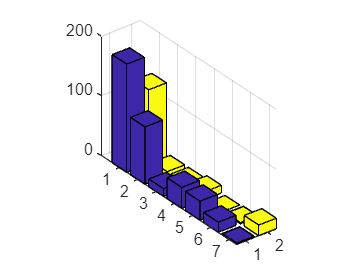

opts = detectImportOptions("TD-foret-chi2_ent.xlsx",ReadVariableNames=true,TextType="string", Range="A:K",VariableNamingRule="preserve");
T = readtable("TD-foret-chi2_ent.xlsx", opts);
T(T.("Caractère saisonnier") == "Mixed", :) = [];

[CT, chi2, p, labels] = crosstab(T.("Région climatique"), T.("Caractère saisonnier"));


bar3(CT)

chi2=chi2

chi2 = 92.2029

## Interprétation du résultat

if p < 0.05 disp('Les variables sont statistiquement dépendantes.');
else disp('Les variables sont indépendantes');
end

Les variables sont statistiquement dépendantes.


## Exemple lorsqu'elles sont indépendantes.

a=discretize(randn(1000,1),-3:3);
b=discretize(randn(1000,1), -2:2);

[CT2, chi2, p, labels] = crosstab(a,b);
CT2

CT2 =      5     8     6     2
    19    52    51    20
    36   110   125    46
    43   125   124    46
    12    39    42     9
     5     5    10     2


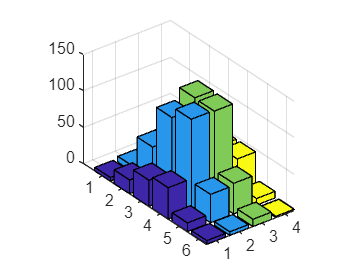


bar3(CT2)

chi2

chi2 = 9.9099